# Undistort diffraction pattern generated by imperfect grating

In this script we show a method to correct distortion caused by diffraction (and imperfect grating). Compare the first image to the very last.

### The image to undistort

We observe the typical pin-cushion distortion caused by diffraction. 

The image was intended to have the 0th order diffraction at the center. However the 0th order is a bit off-center, as can be seen below (the red 'x' marks the center of the image).

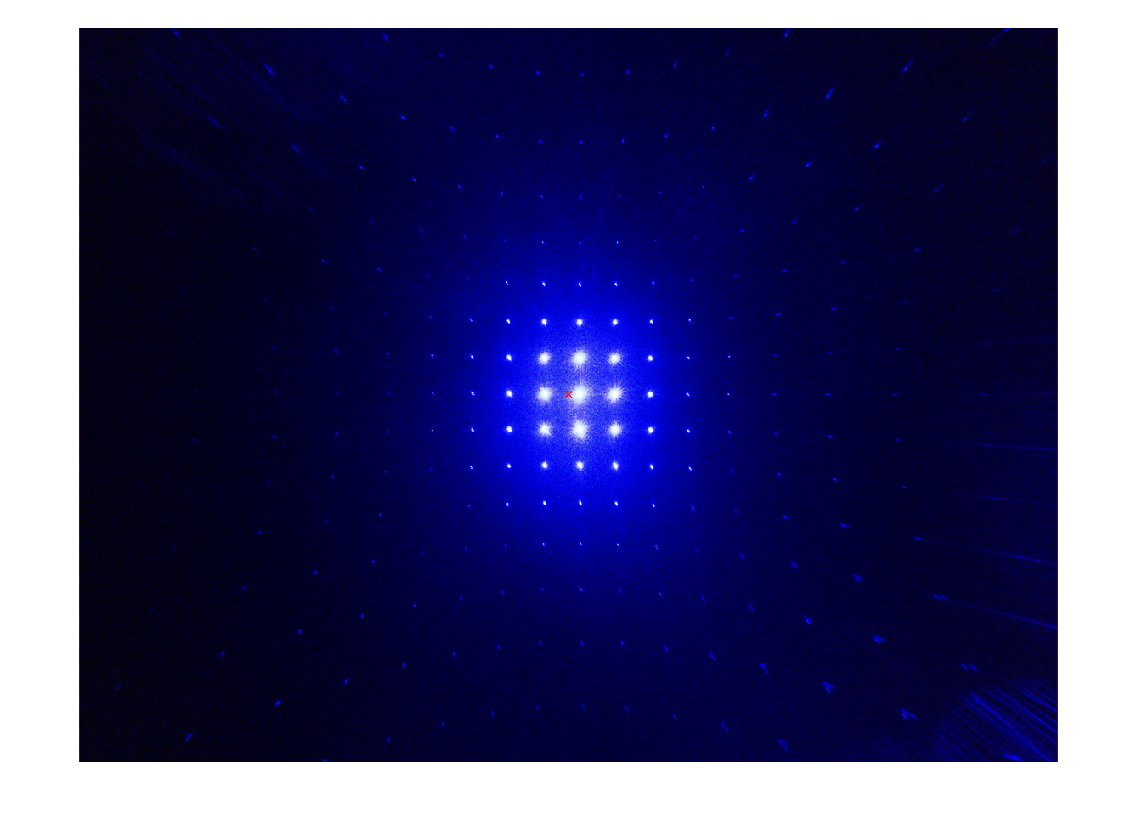

addpath(genpath('..'))

img_fn = "images/devicecal/21/20230511_141541_dec4.png";
img = imread(img_fn);
img_gray=rgb2gray(img);

sz=size(img);
dims=sz([2, 1]);
ctr=(dims+1)/2;

figure
imshow(img)
hold on
plot(ctr(1), ctr(2), 'rx')
hold off

### Define the parameters

The image shown above had been decimated by a factor of 4, so the focal length f below is also scaled by 4 from its original length.

% camera parameters:
pix = 1e-3; % sensor pixel pitch in mm
f = 1.8/4; % focal length in mm

% diffraction parameters:
mord=5; % order of diffraction
lambda=445; % wavelength in nm
d=5000; % period of diffraction grating in nm
unit=lambda/d;

### Find the diffraction points in R-space

The plot below is the result of a few iterations. In general one needs to tweak the (shift, yxratio, theta) parameters, as well as (thres, boxw) below in order to properly bound the diffraction points. The diffraction points are marked with yellow 'x's.

Not all diffraction points need be found. More on this in the subsequent sections.

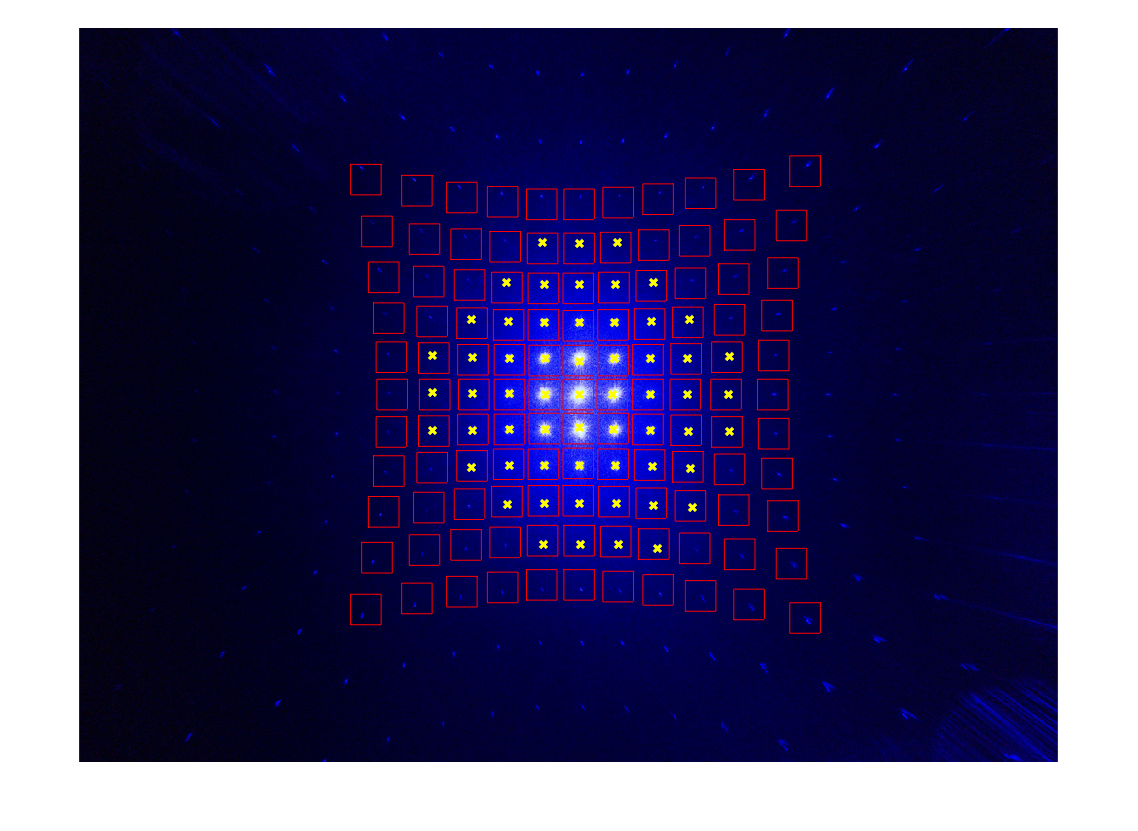

shift=[0.3, 0]; % guessing that the diffraction is 0.3*unit to the right of the image's center
yxratio=1;
theta=0;

thres=90; % intensity threshold
boxw=18; % box width
[XR, YR, ~, bounds]=finddiffrpts(img_gray, mord, unit, shift, yxratio, theta, thres, boxw, dims, pix, f);

figure
imshow(img)
hold on
plot(XR, YR, 'yx', 'linewidth', 2)
for k=1:length(bounds)
    plotbox(bounds(k, 1:2), bounds(k, 3:4), 'r')
end
hold off

### Project the diffraction points to the direction cosine space

Visualize the diffraction points projected onto Q-space (direction cosine space).

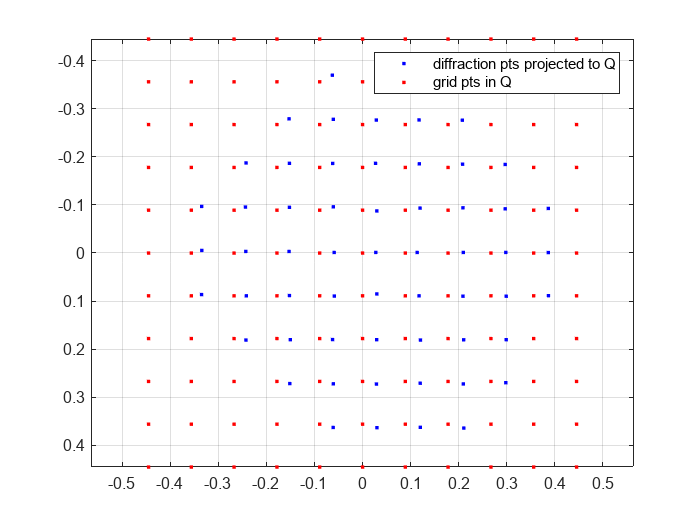

ptsR=[XR(:), YR(:)];
ptsQ = R2Q(ptsR, dims, pix, f);

[gX_Q, gY_Q]=gengrid2d(unit, mord);

figure
plot(ptsQ(:,1), ptsQ(:,2), 'b.')

hold on
plot(gX_Q, gY_Q, 'r.')
hold off
axis equal
set(gca,'ydir','reverse')
grid on
legend('diffraction pts projected to Q', 'grid pts in Q')

### Correct the grating's imperfections

This is done by computing the projective transformation that maps Q-space's grid points to the diffraction points projected onto Q.

In theory only 4 points are required to define a homography. However as finding diffraction points in R-space is not perfect, we like to have > 40 pts.

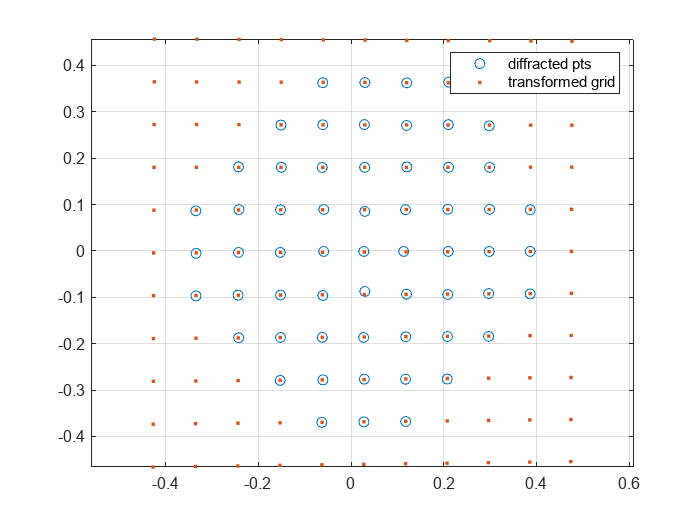

movingPoints=[gX_Q(:), gY_Q(:)];
mask=~isnan(ptsQ(:,1));

tform=fitgeotrans(movingPoints(mask,:), ptsQ(mask,:), 'projective');
movingPoints_t=transformPointsForward(tform, movingPoints);

figure
plot(ptsQ(:,1), ptsQ(:,2), 'o')
hold on
plot(movingPoints_t(:,1), movingPoints_t(:,2), '.')
hold off
axis equal
grid on
legend("diffracted pts", "transformed grid")

### Compute the forward mappings U and V 

[U, V]=getUV(tform, dims, pix, f);

### Transform the image using U and V

Use U and V to *inverse warp* the image to remove the distortion caused by diffraction.

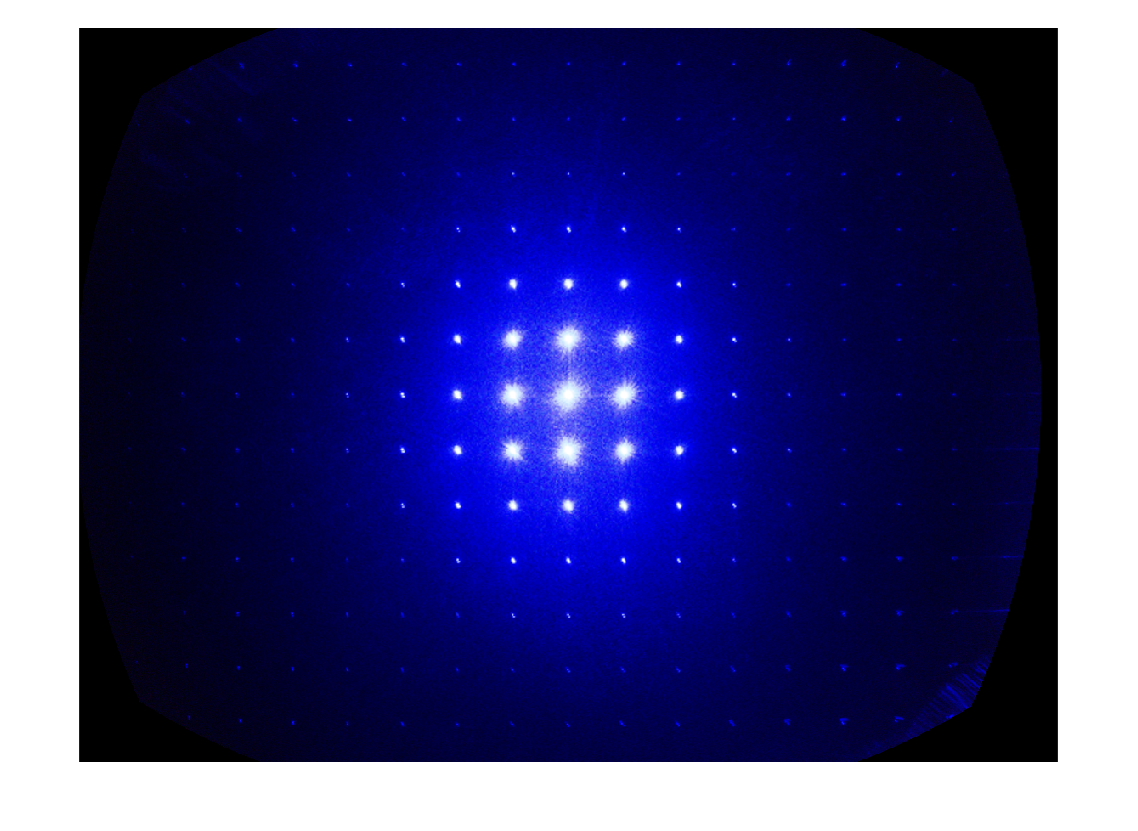

img_t=imtformarray(img, U, V);

figure
imshow(img_t)